# Load Matlab datafile

%clear all;
%load(fullfile('ECG.mat'));
%load(fullfile('ECGNEW2.mat'));
%load(fullfile('ECGNEW.mat'));
%load(fullfile('PPG.mat'));
%load(fullfile('GSR.mat'));
%load(fullfile('ECGPPGNB.mat'));
%load(fullfile('ECGPPGNBS.mat'));
%load(fullfile('ECGGSR.mat'));
%Data = importdata('TT2.csv');
%Data = importdata('ECGACC.csv');
TrainTestData = ECGPPGNEW.Data;
train_n_test_label = ECGPPGNEW.Labels;
%TrainTestData = ECGData.Data;
%train_n_test_label = ECGData.Labels;
%TrainTestData=[TrainD(2:end),TestD(2:end)]
%train_n_test_label=[TrainD(1:), TestD(1:)]



## Split data into testing and training set

%trainData1 = TrainTestData(:,1:45000);
%testData1 = TrainTestData(:,45001:65536);
%trainData1 = TrainTestData(:,1:8000);
%testData1 = TrainTestData(:,8001:16000);
trainData1 = TrainTestData(:,1:16000);
testData1 = TrainTestData(:,16001:32000);


## Feature extraction

%timeWindow = 8192;
timeWindow = 4000; % for ECGPPG, GSR
%timeWindow = 1600; % for ECGPPG, GSR
%timeWindow = 8192; % for ECGPPG, GSR
%timeWindow = 400; %For other signals
%timeWindow = 800;
%timeWindow = 600;
AROrder = 16;
%AROrder = 4;

%transformLevel = 4;
transformLevel = 2;
%transformLevel = 5;
 

[trainFeatures,testFeatures,featureindices]=helperExtractFeatures(trainData1,testData1, timeWindow,AROrder,transformLevel);
allFeatures = [trainFeatures;testFeatures];
allLabels = [train_n_test_label;train_n_test_label];

%allLabels = [train_n_test_labelCopy;train_n_test_labelCopy];

%figure
%%boxplot(allFeatures(:,featureindices.SEfeatures(1)),allLabels,'notch','on')
%boxplot(allFeatures(:,featureindices.SEfeatures(2)),allLabels,'notch','on')
%plot(allFeatures(:,featureindices.SEfeatures(1)))
%ylabel('Entropy')
%title('Feature Extraction')

%plot(allFeatures(:,featureindices.ARfeatures(1)))
%ylabel('AR Coefficient')
%title('Feature Extraction')
%figure
%boxplot(allFeatures(:,featureindices.ARfeatures(1)),allLabels,'notch','on')
%ylabel('Holder Exponent Range')
%title('Range of Singularity Spectrum by Group (First Time Window)')
%grid on

%plot(allFeatures(:,featureindices.WVARfeatures(1)))
%ylabel('Wavelet Variance')
%title('Feature Extraction for PPG')
%boxplot(allFeatures(:,featureindices.WVARfeatures(end)),allLabels,'notch','on')
%ylabel('Wavelet Variance')
%title('Wavelet Variance by Group')
%grid on

%features = [trainFeatures; testFeatures];

## classification

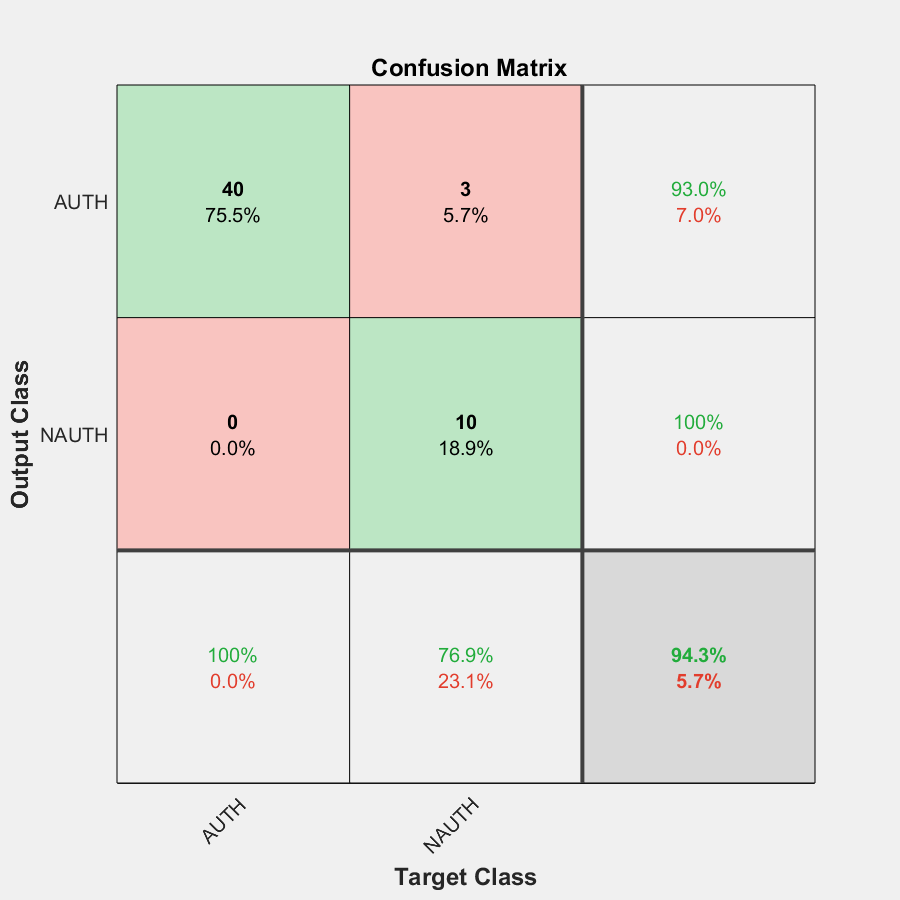

rng(1)


%Mdl = fitcknn(trainData1,train_n_test_label);
modelEN = fitcensemble(trainFeatures,train_n_test_label);
modelKNN = fitcknn(trainFeatures,train_n_test_label);
modelSVM = fitcsvm(trainFeatures,train_n_test_label,'Standardize',true);
predEn = predict(modelEN,testFeatures);
predKNN=predict(modelKNN,testFeatures);
predSVM=predict(modelSVM,testFeatures);



%classOrder = modelEN.ClassNames;
%correctPredictions = strcmp(predLabels,testLabel);
correctPredictionsEN = strcmp(predEn,train_n_test_label);
correctPredictions = strcmp(predKNN,train_n_test_label);
correctPredictionsSVM = strcmp(predSVM,train_n_test_label);
[confusionMatrixEN] = confusionmat(train_n_test_label,predEn);
[confusionMatrix] = confusionmat(train_n_test_label,predKNN);
[confusionMatrixSVM] = confusionmat(train_n_test_label,predSVM);
plotconfusion(categorical(train_n_test_label),categorical(predEn));

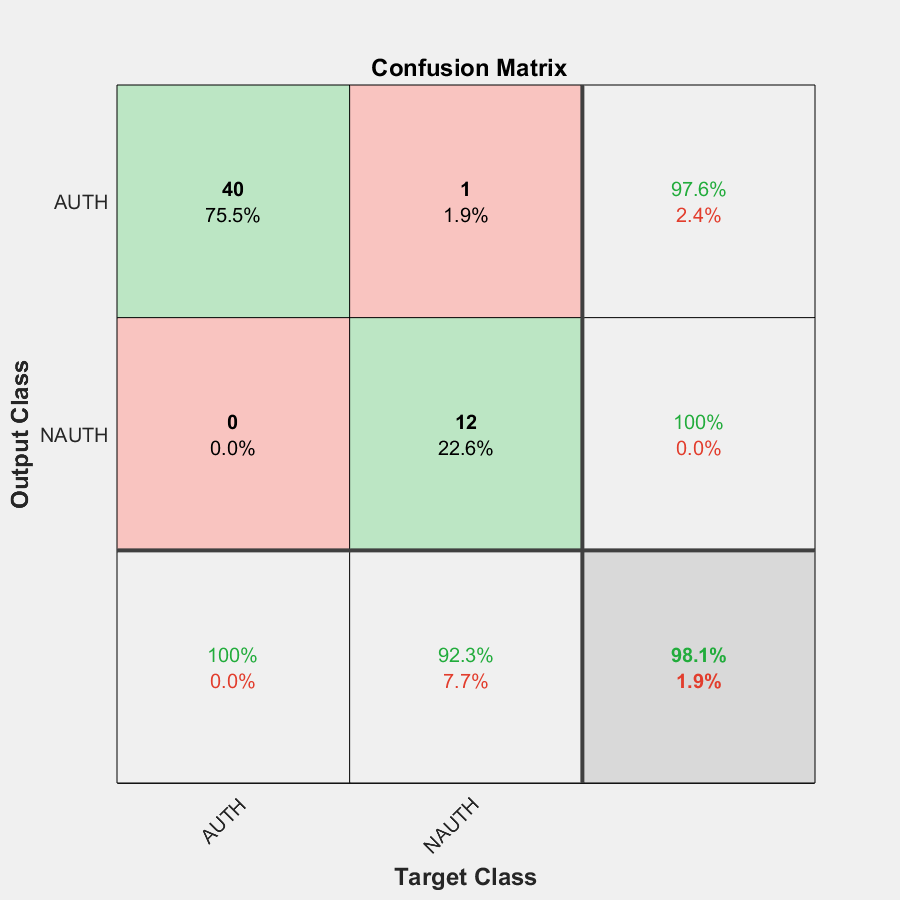

plotconfusion(categorical(train_n_test_label),categorical(predKNN));

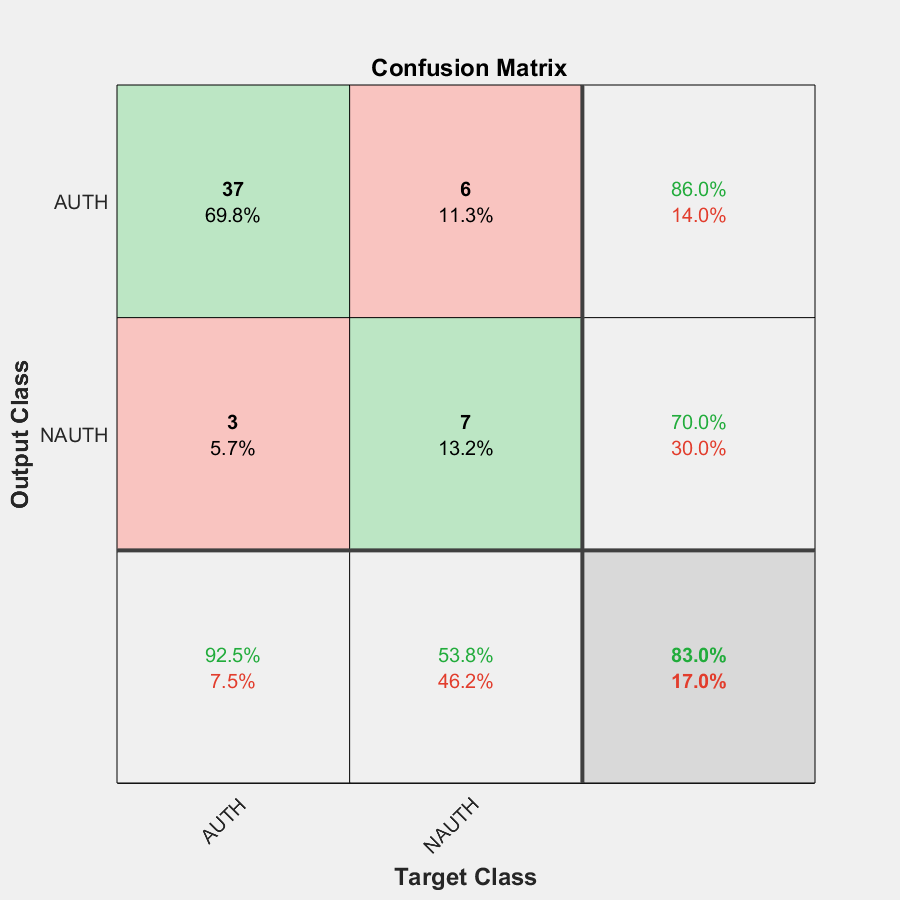

plotconfusion(categorical(train_n_test_label),categorical(predSVM));

%mdlSVM = fitcsvm(testFeatures,predLabels,'Standardize',true);
%mdlSVM = fitPosterior(mdlSVM);

kfoldmodel = crossval(modelKNN,'KFold',5);
classLabels = kfoldPredict(kfoldmodel);
loss = kfoldLoss(kfoldmodel);

%correctPredictionK = strcmp(predKNN,train_n_test_label);
%[confusionMatrixK] = confusionmat(train_n_test_label,predKNN);
%plotconfusion(categorical(train_n_test_label),categorical(predKNN));

## calculate prediction results

truePositive = confusionMatrix(1,1);
falsePositive = sum(confusionMatrix(:,1)) - confusionMatrix(1,1);
falseNegative = sum(confusionMatrix(1,:)) - confusionMatrix(1,1);
trueNegative = confusionMatrix(2,2);

precision = truePositive / (truePositive + falsePositive);
recall = truePositive / (truePositive + falseNegative);
trueNegativeRate = trueNegative / (trueNegative+falsePositive);
falseNegativeRate = falseNegative / (falseNegative+truePositive);
falsePositiveRate= 1 - trueNegativeRate;
truePositiveRate= truePositive/(truePositive + falseNegative);
f1 = 2 * precision * recall / (precision + recall);

## display result

%testAccuracy = sum(correctPredictions) / length(testLabel)*100
testAccuracy = sum(correctPredictions) / length(train_n_test_label)*100;

confusionMatrixTable = array2table([truePositive falsePositive;...
    falseNegative trueNegative],'VariableNames',{'Positive','Negative'},'RowNames',...
    {'Positive','Negative'});

resultTable = array2table([precision recall f1 trueNegativeRate ...
    falseNegativeRate falsePositiveRate],'VariableNames',{'Precision','Recall','F1_Score',...
    'True Negative Rate', 'False Negative Rate', 'False Positive Rate' },'RowNames',...
    {'value',});

disp(confusionMatrixTable);

                Positive    Negative
                ________    ________

    Positive       40           1   
    Negative        0          12   



disp(resultTable);

             Precision    Recall    F1_Score    True Negative Rate    False Negative Rate    False Positive Rate
             _________    ______    ________    __________________    ___________________    ___________________

    value     0.97561       1       0.98765          0.92308                   0                  0.076923      



AUC Curve


%[Xsvm,Ysvm,Tsvm,AUCsvm] = perfcurve(predLabels,score(:,1),'AUTH');
%[Xsvm1,Ysvm2,Tsvm2,AUCsvm2] = perfcurve(predLabels,score(:,2),'NAUTH');
%plot(Xsvm,Ysvm)
%xlabel('False positive rate') 
%ylabel('True positive rate')
%title('ROC for Classification')



